## アンケートデータについて簡単にまとめる

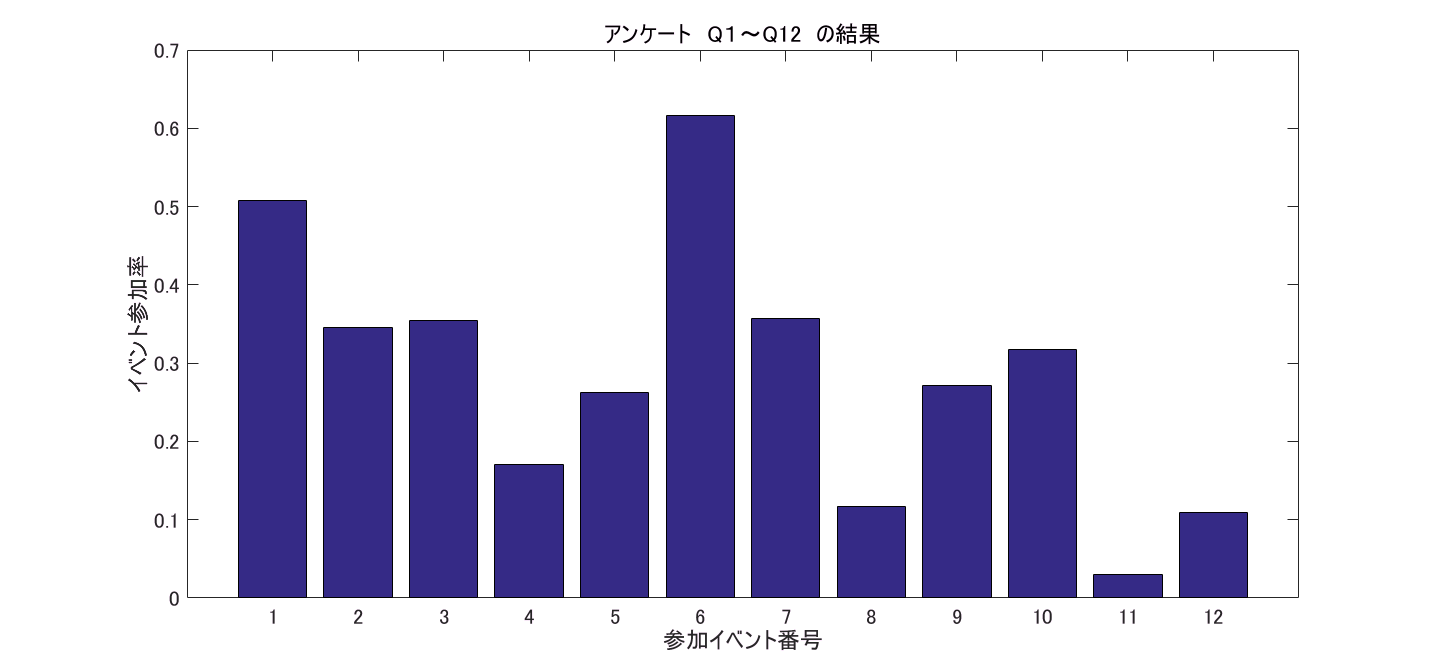

load('Data/ENQUETE.mat')%ENQUETE_5は１～５で答えるものだけ
open('figure/ENQUETE1_12bar.fig')

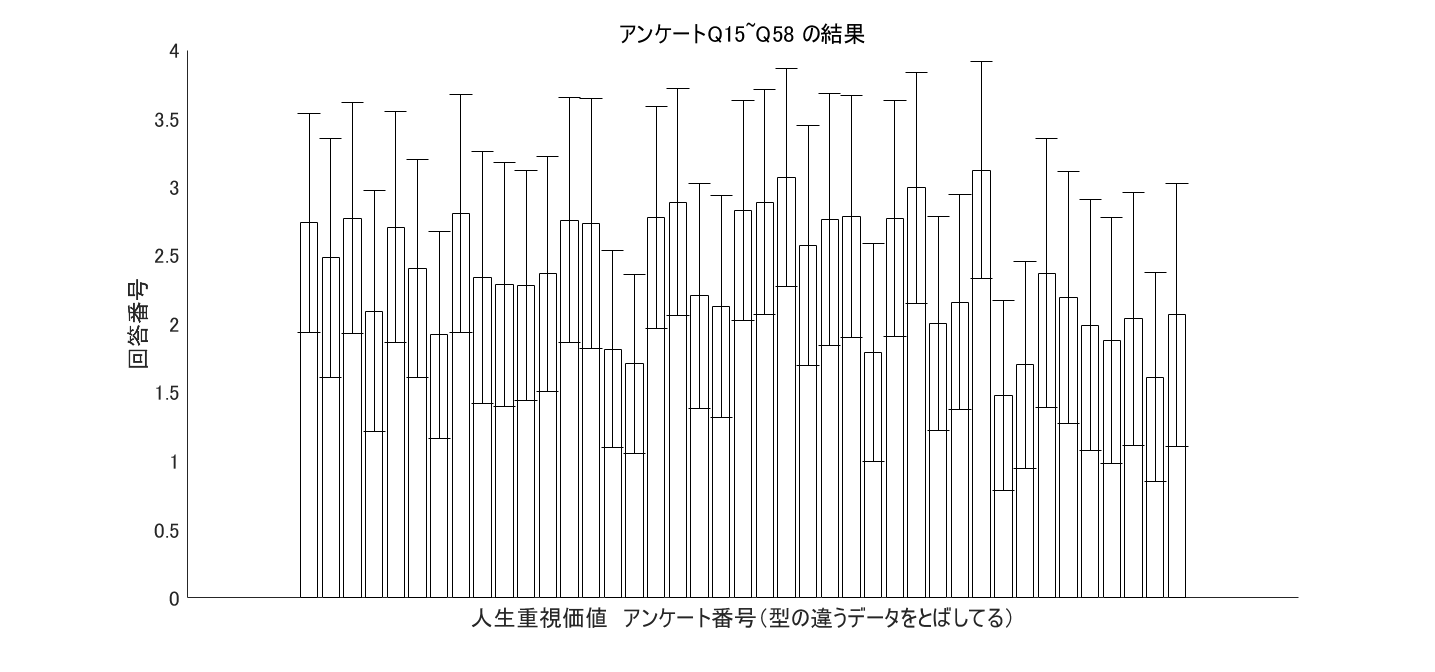

open('figure/ENQUETE15_58errorbar.fig')

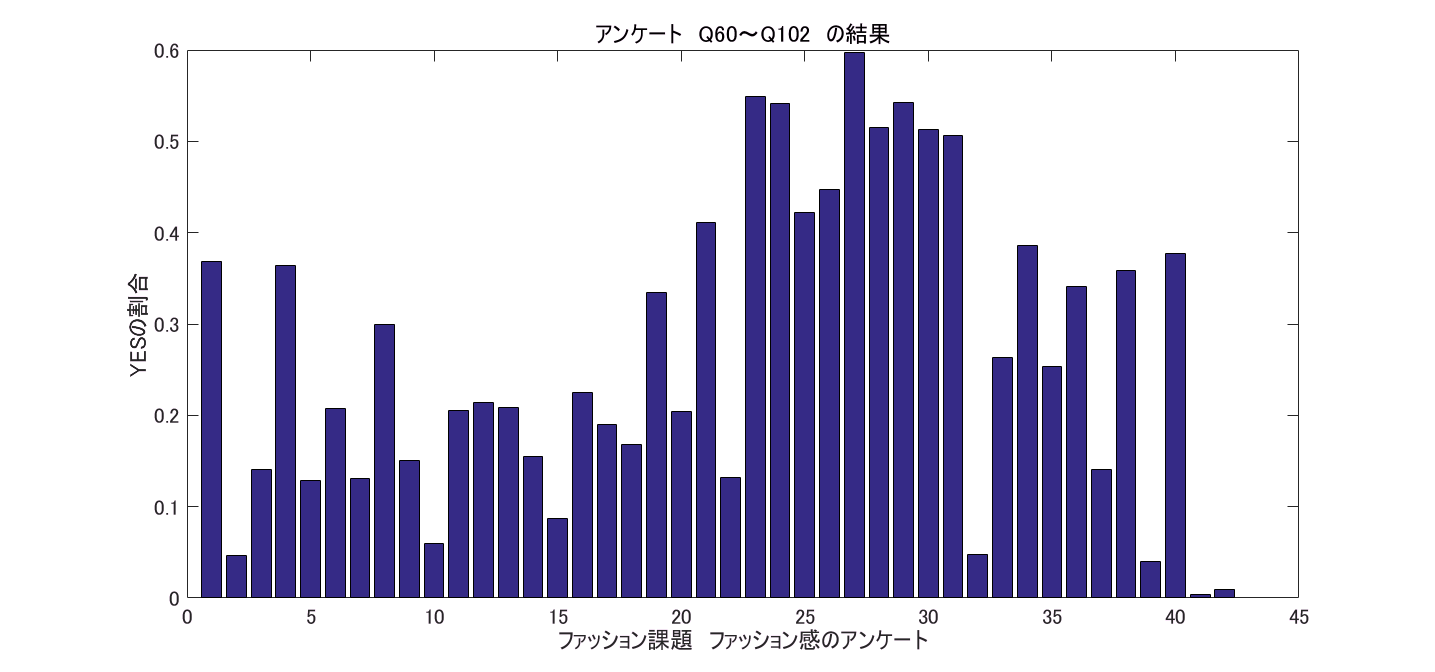

open('figure/ENQUETE60_102bar.fig')


Z_ENQUETE=zscore(ENQUETE_5{:,:})

Z_ENQUETE =     0.3267   -0.5548    0.2711   -1.2444    0.3459   -0.5068    0.1057    0.2255   -0.3691    0.8024   -0.3336   -0.4271    0.2703    0.2932   -1.1376    0.4421    0.2752    0.1320    0.9652    1.0797    0.2166   -2.3007   -0.0847   -0.6541   -0.8283    0.2405    0.2597    0.2667    0.0079    1.2736    1.0669   -0.1542   -0.6900   -0.9266    0.6412    0.8780   -1.0820   -0.9830   -0.0395   -0.8019    0.9733
    0.3267   -0.5548    1.4565    2.1705   -2.0209   -0.5068   -1.2129    1.3763   -1.4545    0.8024    2.0447    0.7395   -0.8478   -1.9044   -1.1376   -1.0870   -2.1936   -1.0711   -1.4663   -0.1551   -1.0304   -2.3007   -2.5958   -1.7985   -1.9156   -0.8916    1.5159    1.4281   -1.1748   -1.2874   -1.4732   -1.4163   -0.6900   -0.9266   -1.3960   -1.2947   -1.0820   -0.9830    1.0412   -0.8019   -1.1120
   -0.9243    1.7449    0.2711    1.0322   -0.8375   -0.5068    0.1057    0.2255    0.7164   -0.3223   -0.3336    1.9060    0.2703    0.2932    1.6512    0.4421   -0.

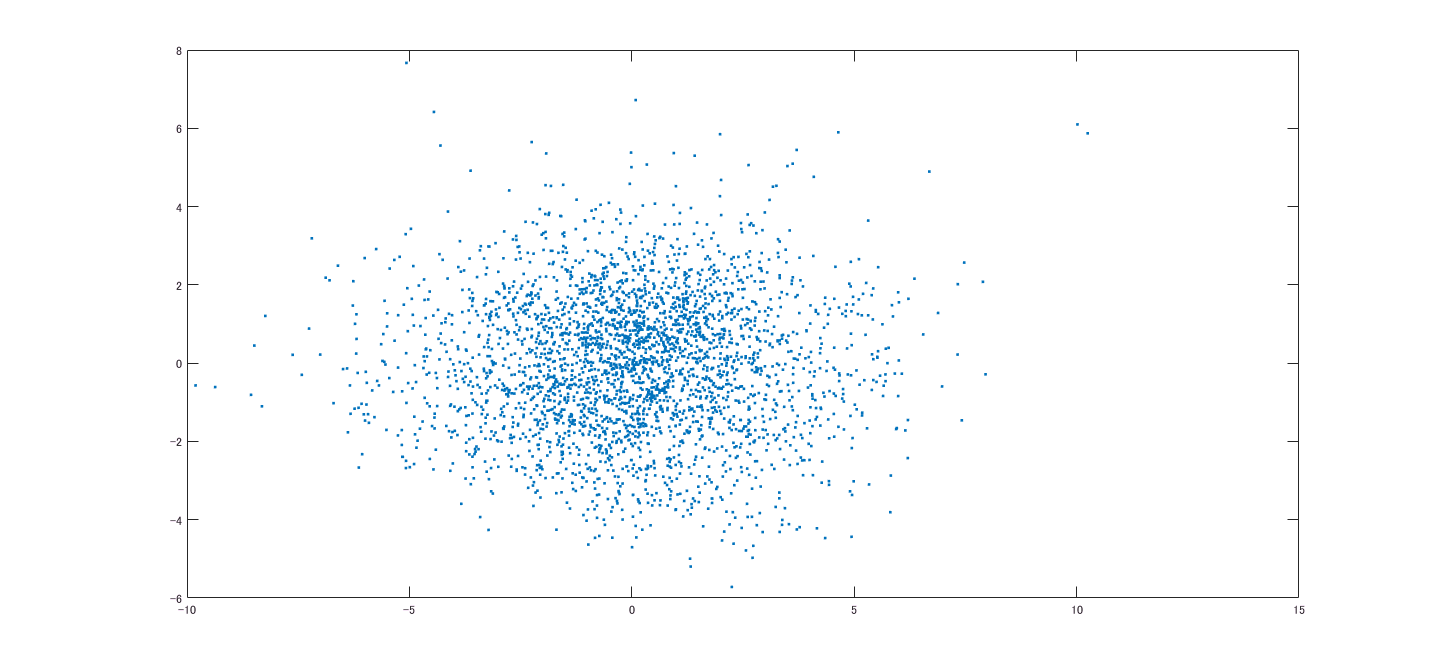

D = pdist(Z_ENQUETE,'euclidean');
[Y,e] = cmdscale(D);
plot(Y(:,1),Y(:,2),'.')

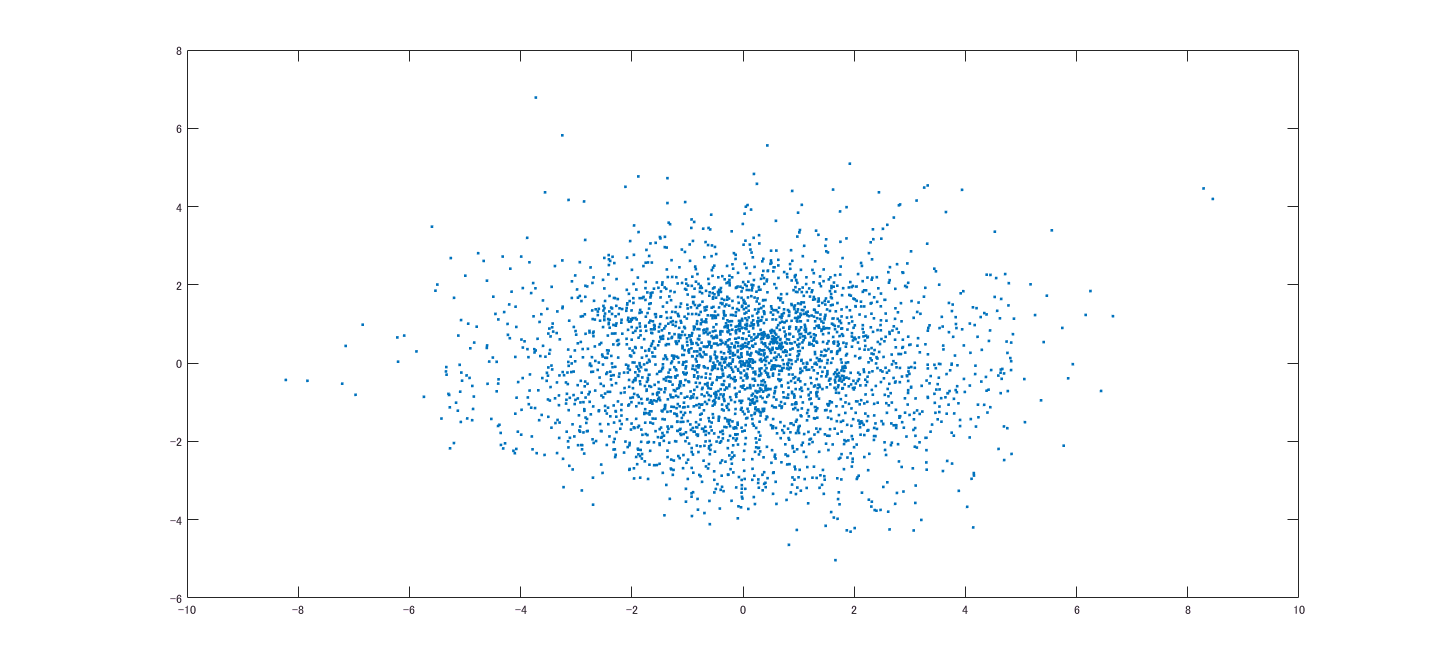

D2 = pdist(ENQUETE_5{:,:},'euclidean');
[Y2,e2] = cmdscale(D2);
plot(Y2(:,1),Y2(:,2),'.')

[pc,score,latent] = pca(ENQUETE_5{:,:})

pc =     0.0832   -0.0876   -0.2180   -0.0731   -0.1057    0.1900   -0.2516    0.2446   -0.0382    0.0610    0.0542    0.0940    0.0539    0.2758    0.0908   -0.1033    0.0967   -0.1759    0.1219   -0.0369    0.0767    0.1618   -0.1647   -0.1288   -0.2072   -0.2354    0.1910    0.1392    0.2650    0.0212    0.3456    0.0812   -0.0963    0.2948   -0.1201    0.1572   -0.1342   -0.0526    0.0547   -0.0652    0.0272
    0.0229    0.0203   -0.0729    0.1438   -0.1802    0.1917   -0.1318    0.4882    0.1749   -0.0141    0.0462    0.4724    0.3136   -0.0170   -0.0611   -0.2135   -0.1413    0.0851   -0.2725   -0.0265    0.0659   -0.0430    0.0767    0.0430    0.2209    0.0418   -0.1215   -0.0092   -0.1382   -0.0301   -0.1693   -0.0479   -0.0093   -0.0329    0.0817   -0.0211   -0.0322    0.0399    0.0024    0.0259    0.0118
    0.1170   -0.1383   -0.0235    0.2906   -0.1419    0.2484   -0.2836    0.0339    0.1437    0.1040   -0.1607    0.0465   -0.2919    0.0149   -0.0221    0.1361    0.0685   

score =     0.1289   -0.0870   -0.2093    0.2997   -0.5917   -1.0440   -0.4011   -0.4003   -1.2426   -0.3286   -1.3383    0.0119    0.9415    1.7332    0.4529    1.0084   -0.2640   -0.1428    0.2929    0.0264    0.7093   -0.5610    0.6252   -1.2503   -0.8772   -0.2371   -0.1251   -0.0483   -0.6371    0.2464   -0.0947    0.2776   -0.0076   -0.3456    0.1983    0.5133    0.4891    0.8153   -0.0636    0.0503    0.0183
   -4.0445   -0.4834   -1.9302    1.2320   -2.1904    0.2319   -0.9617    0.7512    0.6667    0.5037   -1.6836   -2.6667    0.7305   -1.6180   -1.5751    1.0758   -0.2741    0.4904    1.7273   -0.1621   -0.8128   -0.7499   -0.0350   -0.8462    0.0153    0.0647   -0.6065    1.5410    0.1411   -0.3396    0.2488    0.0420   -0.4844    0.8800   -0.2370   -0.1719    0.4524   -0.9515   -0.7786   -0.2019    0.6865
   -1.5820    0.3678    0.3359    1.6416   -1.8755    1.2619    1.7339    0.2825    1.0320   -1.9706   -0.3540    0.6351    0.9049   -0.0382   -0.2796   -0.3839   -1.1376

latent =     4.0807
    2.4466
    1.7364
    1.2528
    1.1659
    1.0787
    1.0386
    0.9183
    0.8422
    0.8105


R2 =cumsum(latent)./sum(latent)

R2 =     0.1405
    0.2247
    0.2845
    0.3277
    0.3678
    0.4049
    0.4407
    0.4723
    0.5013
    0.5292


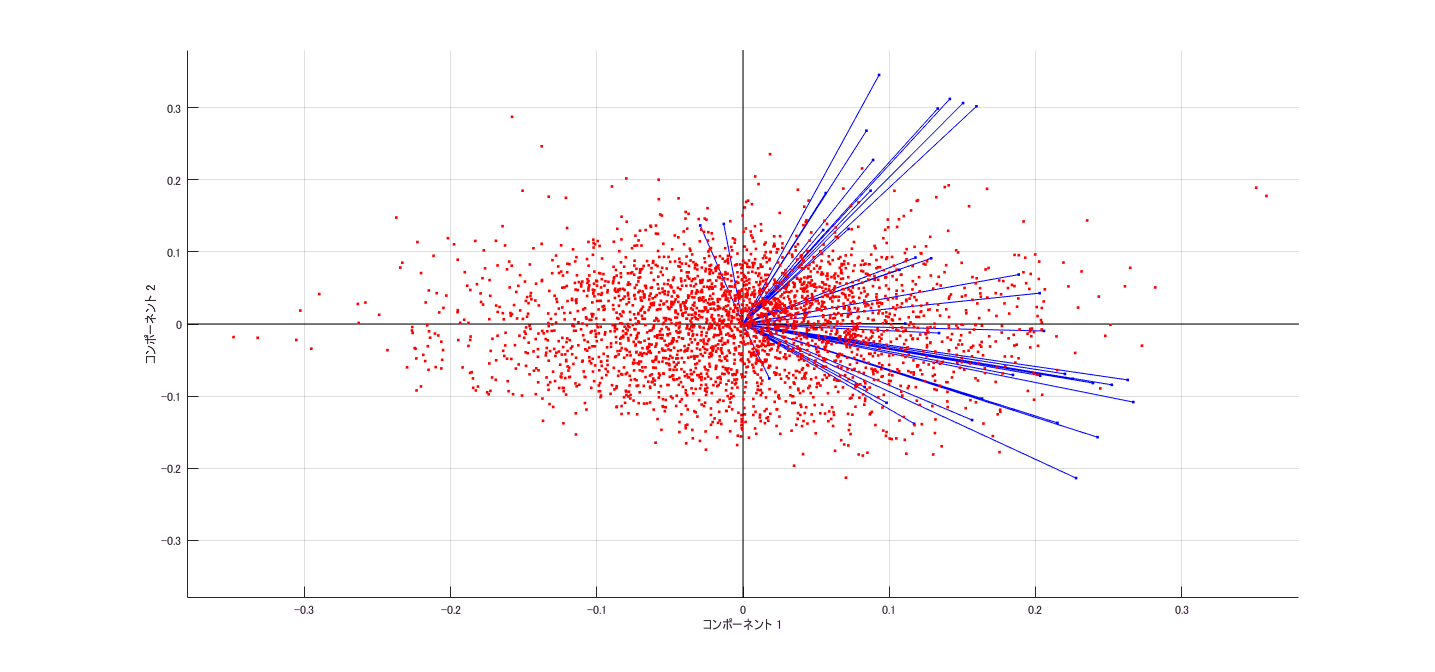

biplot(pc(:,1:2),'Scores',score(:,1:2))

[pc2,score2,latent2] = pca(Z_ENQUETE)

pc2 =     0.0892   -0.0892   -0.2433   -0.1605   -0.2623   -0.1033    0.2190   -0.2479    0.0957   -0.0994   -0.0164    0.1521   -0.1692   -0.2641    0.0746    0.1574    0.0608   -0.2478   -0.0006   -0.0303   -0.1726   -0.0584   -0.0532    0.2313   -0.1283    0.0889    0.2271   -0.1651    0.1268   -0.1579    0.1667   -0.0506    0.2662   -0.2000   -0.1048   -0.1403    0.0387    0.2433   -0.0630   -0.0486    0.0210
    0.0225    0.0272   -0.0946    0.0943   -0.1566   -0.1845    0.2092   -0.2583    0.2880   -0.1073   -0.0945    0.5955   -0.0360    0.0519   -0.1133   -0.3427   -0.0786   -0.0319   -0.0789    0.0441    0.1800    0.1556   -0.0203   -0.0854    0.0536   -0.0408   -0.1883    0.1562   -0.0900    0.0521   -0.0872    0.1048   -0.1753   -0.0197    0.0457    0.0158    0.0860   -0.0499    0.0462    0.0222    0.0117
    0.1174   -0.1485   -0.0548    0.2320   -0.2918   -0.1152    0.3103   -0.0028    0.1274    0.0105   -0.3006   -0.1906    0.0058    0.1007   -0.0504    0.1755    0.1258  

score2 =     0.1868   -0.5024   -0.3757    0.7038   -0.3590   -0.4138   -1.4466   -0.7641   -1.6975    0.7470   -0.8510    0.6101    0.4801   -1.1663    1.1618    0.7394    1.7644   -0.7942    0.2837   -0.4866   -0.7826    1.2479    0.3137   -0.8068   -0.8562    0.2793   -0.2924   -0.5408   -0.2548    0.2344    0.3494   -0.5826   -0.2881    0.4541    0.7076    1.1343   -0.0673    0.2524    0.5031    0.0512    0.0117
   -4.9290   -0.6451   -2.3738    1.2900   -1.9103   -1.9718   -0.2270   -0.4477    0.9542    0.3130    0.1961   -1.9278    3.8012   -0.6386   -0.8275   -0.4416    1.5239    1.6751    0.2743    0.1745   -0.1317    0.4178   -0.3978   -0.4355    0.7827    2.4255    1.0686   -1.1668    0.0154   -0.3087    0.1223    0.8493    0.2617   -0.5338   -0.6457   -0.1798   -0.8317   -0.4403   -1.1442   -0.5524    0.7699
   -1.6860    1.1532   -0.0561    2.1195    1.0584   -2.8865    0.8929    0.2028    0.9781    2.3006    0.9372    1.3741   -0.9251    0.2126   -1.2293   -0.4844   -0.593

latent2 =     5.8963
    3.2023
    2.3175
    1.7982
    1.5591
    1.5107
    1.4454
    1.3393
    1.2401
    1.1671


R2_2 =cumsum(latent2)./sum(latent2)

R2_2 =     0.1438
    0.2219
    0.2784
    0.3223
    0.3603
    0.3972
    0.4324
    0.4651
    0.4953
    0.5238


biplot(pc(:,1:2),'Scores',score(:,1:2))